# MUSI 6202: Final Denoising Project

## Baseline System Overview

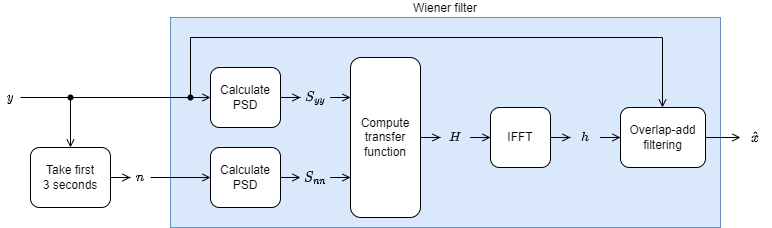

The baseline system is a simple Wiener filter with the noise profile drawing from the first 3 seconds of the noisy signal. The Wiener transfer function were computed in frequency domain from the estimated power spectral densities, then converted back to the time domain. The final filtering was done in the time-domain using overlap-add filtering.

**Description:**

We implemented a moving median filter to the Wiener filter pipeline for our denoising algorithm. Before being input through the Wiener filter, each signal is smoothed through the median filter. By calculating the average value of each signal, we’re able to remove sudden bursts of noise or energy in each signal. We implemented our median filter before the Wiener filter as we hoped to reduce random noise artifacts that may reduce the Wiener filter’s ability to denoise; this way, the Wiener filter can be applied to a much smoother, more accurate signal - improving performance. Additionally, we made a minor tweak to the overlap variable, changing the value from nfft/2 to nfft/8. The smaller hop size equated to improved performance of the filter as it’s better able to retrieve changes as they occur in the signal over time (opposed to a larger hop size that retrieves more of a loose estimation of the signal rather than an accurate representation).

**Toolbox Dependencies: **

- movmedian(y, fs)  (Moving Median)

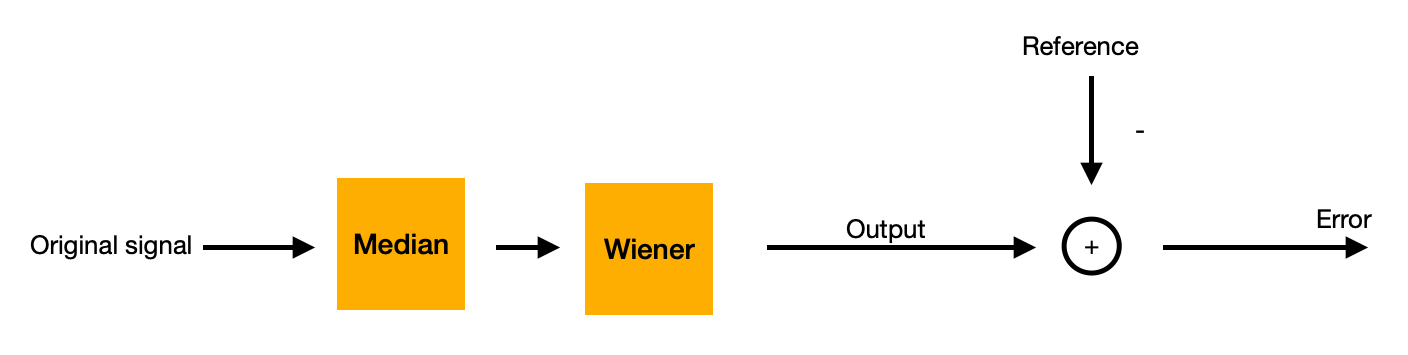

**Citations:**

[1] C. R. Park, S.-H. Kang, and Y. Lee, ‘Median modified wiener filter for improving the image quality of gamma camera images’, *Nuclear Engineering and Technology*, vol. 52, no. 10, pp. 2328–2333, 2020.

**Contributions:**

**Brittney:**

I spent quite a bit of time researching denoising and attempted many (unsuccessful) implementations to improve the baseline system. My initial attempts centered around improving the Wiener filter. I’d read something about improving spectral power estimation so I played around with the Pwelch function and wrote my own as well to improve the baseline; that was a terribly unfruitful use of time. Next, I tried implementing blocking within the Wiener filter to attempt to eke out a bit more accuracy from the algorithm - that was unsuccessful as well. I tried a bit of preprocessing and attempted to implement various filters to improve signal resolution before implementing the Wiener filter but all of those attempts failed as well. I eventually stumbled upon spectral subtraction. I’d attempted a couple different implementations, however I believe the following has the most promise:

    	frame = floor(20*fs/1000);

	o_percent = 60;

	num_osamps = floor(frame*o_percent/100);

	num_samps2shift = frame - num_osamps;

	num_f2process = floor(length(y) / num_samps2shift) - 1;

	e = 2.71828;

	noise_est = mean(noise_profile(1:3));

	k = 1;

	win = hanning(length(frame));

	for i = 1:num_f2process

    	windowed_nsignal = win.*y(k:k+frame-1);

    	y_ft = fft(windowed_nsignal, noiseLengthSampl);

    	mag_ns = abs(y_ft);

    	phase = angle(y_ft);

    	spec_subtraction = mag_ns.^2-noise_est.^2;

    	enhanced_yf = (spec_subtraction.^(1/2).*(e.^1i*phase));

    	enhanced_yt = real(ifft(enhanced_yf));

    	k = k+num_samps2shift;

	end

THIS ALSO DID NOT WORK! Which was pretty frustrating because, by this point, I thought I was getting closer to minor improvement of the baseline. Feedback on the code above would be greatly appreciated if possible. Early on in the project when I was attempting to improve the Wiener filter, I noticed the hop size had a pretty significant effect on the filter. So I played around with different values and found nfft/8 to be the most effective hop size. Not the most significant or meaningful, but it certainly contributed to the overall improvement of the baseline. Additionally, I completed the description and diagram of our system.

**Dani**:

We used my in-class wiener filter for this assignment. I also helped to rearrange the code so we adhered to the API specification and added comments. I researched ways to more cleverly implement this median filter, but was not successful in creating a recursive implementation. 

**Evan:**

I went online and read various papers on different types of denoising filters comparing the pros and cons. At first I thought it might be best for us to use a Kalman filter for our denoising filter since it has a decent SNR filter for speech. However, I heard from some sources that the Kalman filter doesn’t seem to work for music: [https://ccrma.stanford.edu/~orchi/Documents/thesis_KF.pdf](https://ccrma.stanford.edu/~orchi/Documents/thesis_KF.pdf). My suggestions of using an adaptive filter led to our group deciding to implement a median filter (similar to a Wiener filter but with some statistical filtering beforehand). I then put together all the citations for the code/methods used in our project.

**Joey:**

Joey worked on implementing the moving median filter before our baseline wiener filter implementation.

addpath(genpath("./src"));

## Evaluation on the development set

devDataPath = "./data/dev";

devDataFolders = dir(devDataPath);
devDataFolders = devDataFolders(3:end);

nDevSamples = size(devDataFolders, 1);

initSnr = NaN(nDevSamples, 1);
finalSnr = NaN(nDevSamples, 1);

for i = 1:nDevSamples
    noisyFile = fullfile(devDataPath, devDataFolders(i).name, "noisy.wav");
    cleanFile = fullfile(devDataPath, devDataFolders(i).name, "clean.wav");

    [noisySig, fs] = audioread(noisyFile);
    [cleanSig, fsc] = audioread(cleanFile);

    assert(fs == fsc);

    estimSig = denoise(noisySig, fs);
    
    initSnr(i) = computeSnr(cleanSig, noisySig);
    finalSnr(i) = computeSnr(cleanSig, estimSig);    
end

deltaSnr = finalSnr - initSnr;

### Result statistics

fprintf("Input SNR (dB)");

Input SNR (dB)

descStats(initSnr);

min    	median 	mean   	max    	std    
-11.90	-2.16	-1.89	-2.16	-1.89
-2.16	-1.89	-2.16	-1.89	-2.44
-1.89	-1.89	-1.89	-1.89	-1.89
-1.89	-1.89	-1.89	-1.89	-0.70
-0.70	-0.70	-0.70	-0.70	-0.70
-0.70	-0.70	-0.70	-0.70	-0.70
-0.70	-0.70	0.23	0.23	0.23
0.23	0.23	2.87	2.87	0.23
0.23	0.23	0.23	0.23	0.23
0.23	0.23	-1.95	-2.04	-2.04
-1.95	-1.95	-1.95	-1.95	-1.95
-1.95	-1.95	-1.95	-1.04	-1.04
-1.95	-1.95	-1.04	-1.04	-1.04
3.14	3.14	3.14	3.14	3.14
3.83	3.86	3.83	3.83	3.83
3.86	3.83	3.86	3.86	3.86
3.86	3.86	1.76	3.86	1.76
1.76	1.76	1.76	1.76	1.76
1.76	1.76	1.76	1.76	4.79
4.79	4.79	4.79	4.79	4.79
4.79	4.79	4.79	4.79	7.00
7.00	7.00	7.00	7.00	7.00
7.00	7.00	7.00	7.00	7.00
7.00	7.00	4.07	4.07	1.54
1.54	1.54	1.54	1.54	1.54
-4.17	-4.17	-4.17	-4.17	-4.17
-4.17	-4.17	-4.17	-4.17	-4.17
-4.17	-4.17	-4.17	-4.17	-4.17
-4.17	-4.17	1.82	1.82	-4.17
1.82	1.82	1.82	1.82	1.82
1.82	1.82	1.82	1.82	1.82
1.82	1.82	1.82	1.82	1.82
1.82	1.82	6.84	6.84	6.84
6.84	6.84	6.84	6.84	6.84
6.84	6.84	6.84	7.21	7.21
6.84	6.84	7.21	6


fprintf("Output SNR (dB)");

Output SNR (dB)

descStats(finalSnr);

min    	median 	mean   	max    	std    
-6.76	0.95	1.08	1.13	1.18
1.57	1.96	1.57	1.96	1.96
2.10	2.10	2.10	2.11	2.11
2.11	2.48	2.65	3.30	3.55
3.30	3.30	3.30	2.65	3.30
3.30	2.67	2.67	2.67	2.65
2.67	2.67	2.67	2.67	2.67
2.67	3.30	3.34	3.34	3.30
2.67	3.34	3.34	1.94	1.94
1.94	1.94	1.60	1.53	1.53
1.53	1.53	1.53	1.53	1.53
1.53	1.53	1.73	2.26	2.26
2.26	2.26	2.42	3.11	3.11
3.32	3.32	3.32	3.32	3.32
4.19	5.06	4.19	4.19	4.86
4.86	4.19	4.86	4.19	4.19
4.19	4.19	4.19	4.24	4.24
4.24	4.24	4.24	4.24	3.05
3.88	4.24	3.88	3.88	4.24
4.24	4.24	4.84	3.88	4.60
3.88	3.88	4.60	4.10	4.60
4.60	4.10	4.60	6.34	7.09
4.60	4.60	4.60	4.60	7.09
7.09	7.09	4.29	4.29	4.15
4.15	4.15	4.15	3.59	3.28
1.17	3.28	1.17	1.17	1.17
1.08	1.08	1.08	1.17	0.64
1.35	2.34	2.34	3.28	2.34
3.34	2.34	3.34	3.34	2.34
3.07	3.07	3.75	3.07	3.75
3.75	3.77	3.77	3.77	3.77
3.77	3.77	3.97	3.65	5.09
5.61	5.61	5.80	5.88	5.80
5.88	5.88	5.88	4.69	5.88
5.88	6.19	6.25	6.27	6.27
6.25	6.25	6.27	5.01	5.78
5.01	5.78	5.01	5.01	3.56
3.56	0.69	0.69	0.65	0.65
0.69	1.54


fprintf("Change in SNR (dB)");

Change in SNR (dB)

descStats(deltaSnr);

min    	median 	mean   	max    	std    
-4.18	3.36	3.10	3.36	3.62
3.80	3.98	3.80	3.98	3.98
3.98	3.10	3.98	4.00	3.98
4.00	3.98	3.98	3.35	2.93
2.93	2.93	3.35	3.35	3.35
3.65	3.65	3.65	3.35	3.65
3.35	3.35	2.12	2.12	2.79
2.79	2.79	2.12	2.12	2.79
2.79	2.79	2.79	2.79	2.55
2.55	2.55	2.55	2.79	3.11
3.11	3.14	3.14	3.14	2.55
2.19	2.55	2.19	2.19	2.19
3.30	3.30	3.30	1.92	1.92
1.92	1.87	1.87	1.53	1.41
1.41	0.56	1.41	1.41	1.41
0.56	1.41	1.41	1.41	1.41
0.56	0.56	1.41	1.69	2.07
2.07	2.07	2.07	2.48	2.07
2.12	2.07	2.12	2.12	1.69
1.69	1.69	1.05	1.05	-1.41
1.05	1.05	1.05	1.05	1.05
1.05	1.44	0.09	0.09	0.09
1.44	1.44	1.44	0.22	0.22
0.22	0.22	0.22	0.22	2.05
2.05	1.46	1.46	2.05	2.05
2.61	2.61	3.49	3.49	3.49
3.49	5.34	4.72	3.49	3.49
3.60	4.72	4.95	4.72	4.95
4.72	4.72	3.60	3.60	4.72
4.72	4.72	3.60	4.95	4.95
4.95	3.27	1.94	1.94	1.94
1.94	1.83	1.60	1.83	1.60
1.60	1.60	-0.14	-0.14	-0.53
-0.14	0.71	0.71	0.78	0.71
0.71	-0.53	0.29	-0.53	-0.53
0.29	0.29	0.29	0.29	0.29
0.29	-0.94	0.29	0.29	0.78
0.78	1.97	3.87	5.14	5.14


### Visualizing results

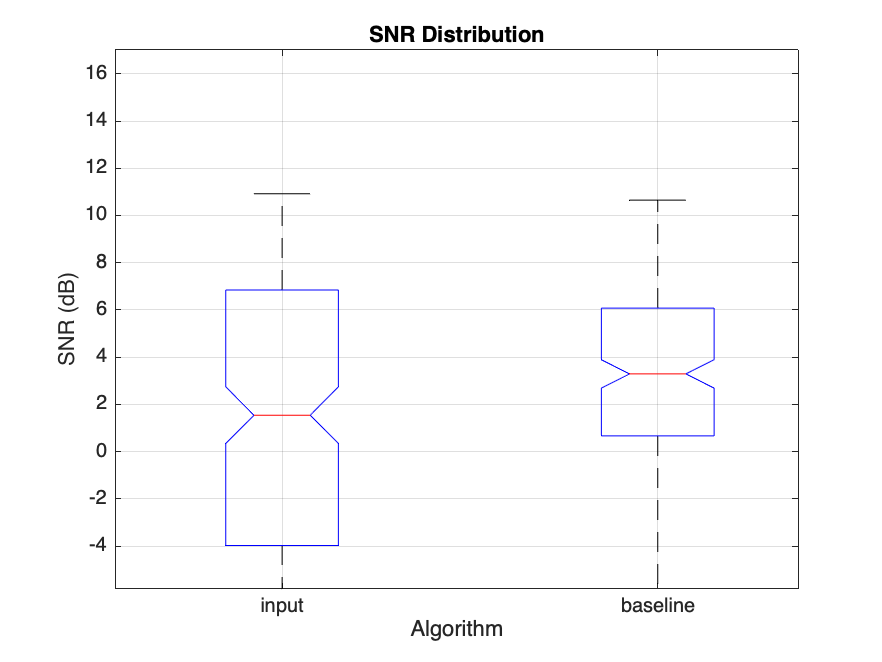

figure;
boxplot([initSnr, finalSnr], ...
    'Notch', 'on', ...
    'Labels', ["input", "baseline"] ...
);
title("SNR Distribution");
xlabel("Algorithm");
ylabel("SNR (dB)");
grid;

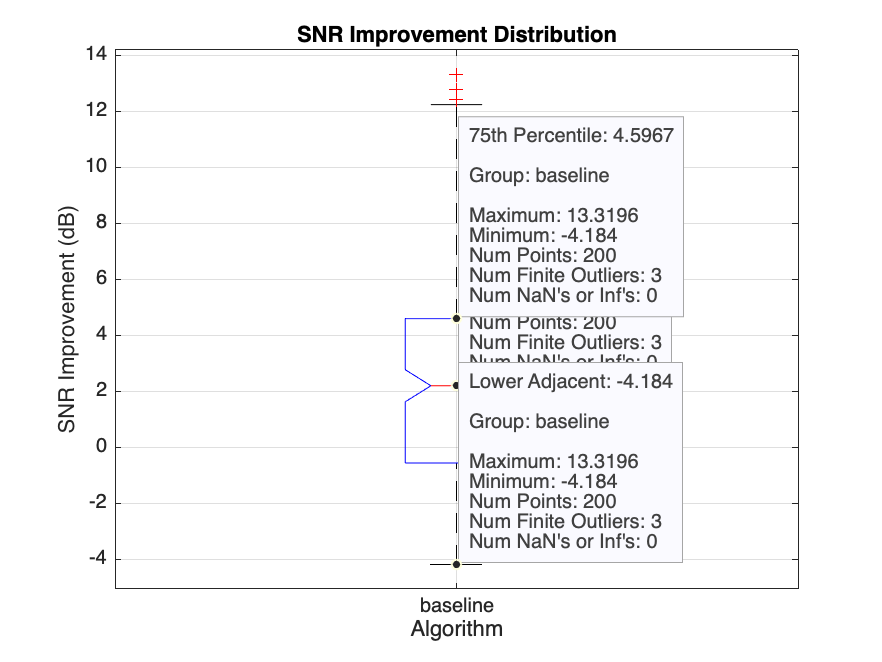

figure;
boxplot(deltaSnr, ...
    'Notch', 'on', ...
    'Labels', "baseline" ...
);
title("SNR Improvement Distribution");
xlabel("Algorithm");
ylabel("SNR Improvement (dB)");
grid;

## Profiling

profile clear

nProfileSamples = 10;

profile on
for i = 1:nProfileSamples
    noisyFile = fullfile(devDataPath, devDataFolders(i).name, "noisy.wav");
    cleanFile = fullfile(devDataPath, devDataFolders(i).name, "clean.wav");

    [noisySig, fs] = audioread(noisyFile);
    [cleanSig, fsc] = audioread(cleanFile);

    assert(fs == fsc);
    
    estimSig = denoise(noisySig, fs);
end
profile off

p = profile('info');
profsave(p, "./doc/profile");

The file /./doc/profile/file0.html does not exist.



profile viewer;